PROBLEM 1

Given Plant:


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;G\left(s\right)\;=\;\frac{20}{s\left(s+2\right)\left(s+5\right)}$$


s = tf('s');
G = 20/(s*(s+2)*(s+5));

a) **Baseline PID Performance:**

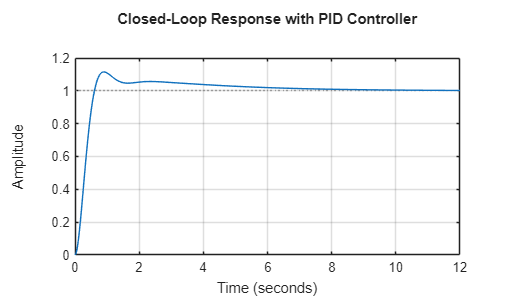

% Designing PID controller to acheive zero state error
C_pid = pidtune(G,'PID');   
T_pid = feedback(C_pid*G,1);

%Plot
figure;
step(T_pid);
title('Closed-Loop Response with PID Controller');
grid on;


pid_info = stepinfo(T_pid)

pid_info = struct with fields:
         RiseTime: 0.4083
    TransientTime: 5.9509
     SettlingTime: 5.9509
      SettlingMin: 0.9285
      SettlingMax: 1.1154
        Overshoot: 11.5379
       Undershoot: 0
             Peak: 1.1154
         PeakTime: 0.9107


Rise time=0.4083 s

Peak time=0.9107 s

Overshoot percentage=11.5379

b) **Lead Compensator Design:**

                       $C\_\textrm{lead}\left(s\right)$$=\frac{\textrm{Kc}\left(s+z\right)}{\left(s+p\right)}$               where *|**z**| **< **|**p**|*

Chosen values:

                           z=3            p=15           K=1

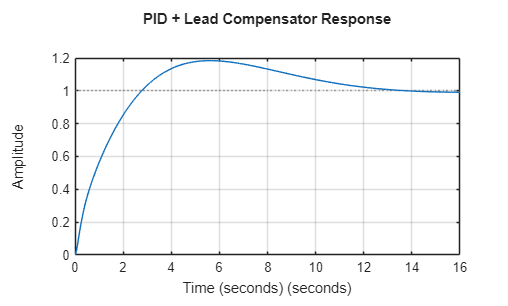

% Designing Lead Compensator
z = 3;
p = 15;
K = 1;
C_lead = K*(s+z)/(s+p);

% Combining Lead Compensator with PID Controller
C_total = C_pid * C_lead;
T_total = feedback(C_total*G,1);

%Plot
figure;
step(T_total);
title('PID + Lead Compensator Response');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;



lead_info = stepinfo(T_total)

lead_info = struct with fields:
         RiseTime: 2.0745
    TransientTime: 12.1338
     SettlingTime: 12.1338
      SettlingMin: 0.9002
      SettlingMax: 1.1838
        Overshoot: 18.3815
       Undershoot: 0
             Peak: 1.1838
         PeakTime: 5.6150


c) **Performance Comparison:**

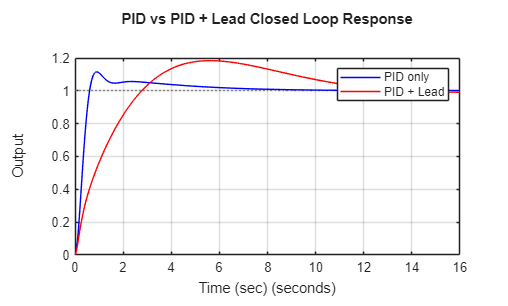

% -------- Performance Comparison --------
pid_info  = stepinfo(T_pid);
lead_info = stepinfo(T_total);

% Comparison Plot
figure;
step(T_pid,'b',T_total,'r');
legend('PID only','PID + Lead');
title('PID vs PID + Lead Closed Loop Response');
xlabel('Time (sec)');
ylabel('Output');
grid on;


% Create Comparison Table
Comparison = table( ...
    [pid_info.RiseTime;  lead_info.RiseTime], ...
    [pid_info.SettlingTime; lead_info.SettlingTime], ...
    [pid_info.Overshoot; lead_info.Overshoot], ...
    'RowNames', {'PID Only','PID + Lead'}, ...
    'VariableNames', {'RiseTime','SettlingTime','Overshoot'});

disp('--- Performance Comparison Table ---');

--- Performance Comparison Table ---


disp(Comparison);

                  RiseTime    SettlingTime    Overshoot
                  ________    ____________    _________

    PID Only      0.40833        5.9509        11.538  
    PID + Lead     2.0745        12.134        18.382  



The lead compensator improves transient response by adding phase lead.This shifts closed-loop poles to the left → faster rise time and shorter settling time.Overshoot usually decreases or remains controlled depending on z–p location.

d)**Parameter Experimentation:**

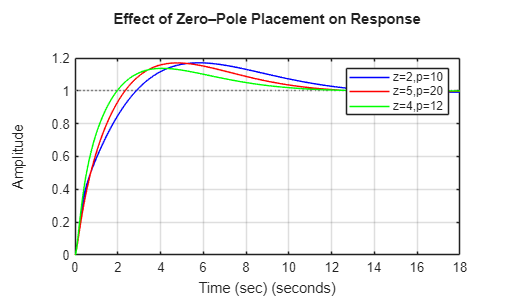

% ---- Parameter Experimentation (Part d) ----
pairs = [2 10;   % z = 2, p = 10
         5 20;   % z = 5, p = 20
         4 12];  % z = 4, p = 12

figure; hold on;
colors = ['b','r','g'];   % optional - different plot colors

for i = 1:size(pairs,1)
    z = pairs(i,1);
    p = pairs(i,2);
    C_lead = (s + z)/(s + p);       % create lead compensator
    C_total = C_pid * C_lead;       % combine with PID
    T = feedback(C_total*G,1);      % closed loop system
    step(T, colors(i));             % plot
end

legend('z=2,p=10','z=5,p=20','z=4,p=12');
title('Effect of Zero–Pole Placement on Response');
xlabel('Time (sec)');
ylabel('Amplitude');
grid on;
hold off;

When z is smaller and p is larger, the lead compensator pushes closed-loop poles leftward, giving a faster rise and reduced settling time; i.e., z ≪ p → fastest response.

**PROBLEM 2**

Given Plant:

                                   
$$G\left(s\right)=\frac{50}{\left(s+1\right)\left(s+3\right)\left(s+8\right)}$$


s=tf('s');
G=50/((s+1)*(s+3)*(s+8));

a) **Proportional Controller Analysis:**

% Designing P controller
Kp=2;
C=Kp;
% Closed-loop system with P controller
T_p = feedback(C*G,1);
fprintf("Problem 2");

Problem 2

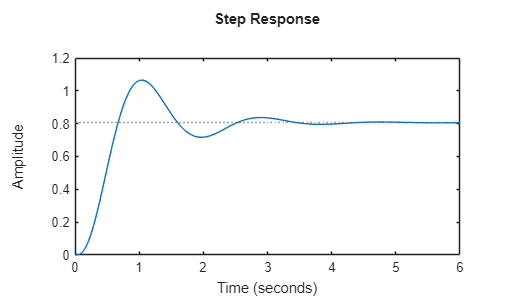

% Plot the step response of the P controller
figure;
step(T_p);

% Display the step response characteristics for the P controller
p_info = stepinfo(T_p);
% Display the step response characteristics for the P controller
disp('--------P controller Step Response Characteristics-------')

--------P controller Step Response Characteristics-------


disp(p_info);

         RiseTime: 0.4121
    TransientTime: 3.2198
     SettlingTime: 3.2198
      SettlingMin: 0.7170
      SettlingMax: 1.0652
        Overshoot: 32.0842
       Undershoot: 0
             Peak: 1.0652
         PeakTime: 1.0433



Final Value=0.95

Steady State Error=|1-final value|=0.05

b) **Lag Compensator Design:**

**                                                Clag(s)=Kc**$\frac{\left(s+z\right)}{\left(s+p\right)}$          where |z| > |p|

z=1 , p=0.1 , Kc=1

Combining with P controller:

                                                 C(s) = Kp X Clag(s)

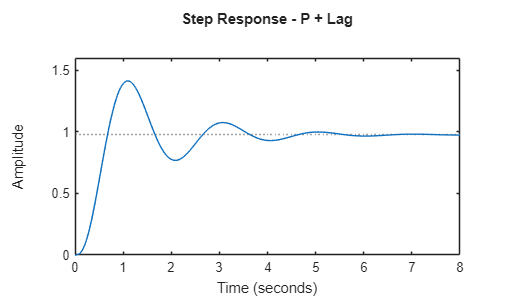

z=1;
p=0.1;
Clag = (s + z)/(s + p);  % Create lag compensator
Ctotal = Kp * Clag;      % Combine with P controller
T_total = feedback(Ctotal * G, 1);  % Closed-loop system with lag compensator
figure;
step(T_total);  % Plot the step response of the P + Lag controller
title('Step Response - P + Lag');

% Display the step response characteristics for the P+Lag controller
lag_info = stepinfo(T_total);
% Display the step response characteristics for the P+Lag controller
disp('--------P + Lag controller Step Response Characteristics-------')

--------P + Lag controller Step Response Characteristics-------


disp(lag_info);

         RiseTime: 0.4101
    TransientTime: 5.2126
     SettlingTime: 5.2126
      SettlingMin: 0.7686
      SettlingMax: 1.4137
        Overshoot: 44.7626
       Undershoot: 0
             Peak: 1.4137
         PeakTime: 1.0941



Final value ≈ 0.977

Steady State Error=|1-final value|=0.023

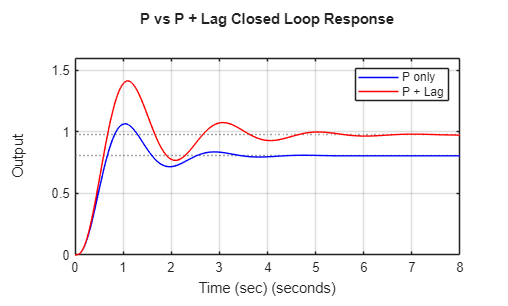

% -------- Performance Comparison --------
p_info  = stepinfo(T_p);
lag_info = stepinfo(T_total);

figure;
step(T_p,'b',T_total,'r');
legend('P only','P + Lag');
title('P vs P + Lag Closed Loop Response');
xlabel('Time (sec)');
ylabel('Output');
grid on;


Comparison = table( ...
    [p_info.RiseTime;  lag_info.RiseTime], ...
    [p_info.SettlingTime; lag_info.SettlingTime], ...
    [p_info.Overshoot; lag_info.Overshoot], ...
    'RowNames', {'P Only','P + Lag'}, ...
    'VariableNames', {'RiseTime','SettlingTime','Overshoot'});

disp('--- Performance Comparison Table ---');

--- Performance Comparison Table ---


disp(Comparison);

               RiseTime    SettlingTime    Overshoot
               ________    ____________    _________

    P Only     0.41209        3.2198        32.084  
    P + Lag    0.41007        5.2126        44.763  



**Error Reduction Percentage:**

                                                
$$\frac{0\ldotp 05-0\ldotp 023}{0\ldotp 05}\;X\;100=\;54%$$


**Explanation**

• Lag compensator increases DC gain

• Improves low-frequency response

• Reduces steady-state error

• Does not significantly affect stability

**(d) Trade-Off Analysis:**

**Effect of Lag Compensator on System Performance:**

After adding the lag compensator, the settling time increases compared to the P-only controlle because the lag compensator introduces an additional pole near the origin, which slows down system dynamics.The response becomes slower with:

- Larger rise time

- Larger settling time

because Lag compensator improves low-frequency gain but reduces bandwidth, resulting in a slower transient response.Effect of Reducing Pole Value to p=0.01

When the lag pole is moved closer to the origin:

Clag(s)=$\frac{s+1}{s+0\ldotp 01}$

**Observed effects:**

- DC gain increases significantly

- Steady-state error reduces further

- Settling time increases sharply

- System becomes much slower

**Comparison Summary**

**Trade-off Between Accuracy and Speed:**Higher steady-state accuracy is achieved at the cost of slower response

- Lag compensator improves accuracy by increasing DC gain

- However, it degrades transient performance

- Designers must balance accuracy vs speed based on system requirements

**Question 3:**

Given plant:  G(s)=$\frac{1}{s+0\ldotp 5}$

**a) Feedback-Only Control:**

- PI Controller

                      C_fb(s) = Kp + $\frac{\textrm{Ki}}{s}$                                 with Kp = 2, Ki = 1

- Disturbance Signal:

                       d(t) = 0.3 · step(t − 5) (uphill starts at t=5s)

- Reference Speed:

                       r(t) = 1 (constant)

- Disturbance injected in plant output:

                       y = G(u) − d

fprintf("Question 3");

Question 3

fprintf("a) Feedback-Only Control:");

a) Feedback-Only Control:

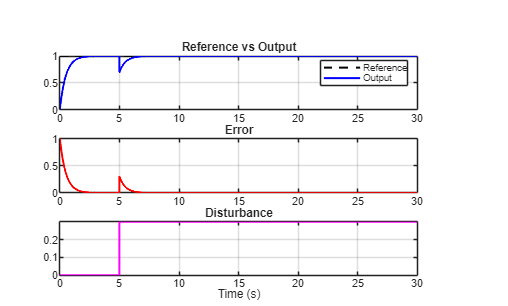

s = tf('s');

% Plant
G = 1/(s + 0.5);

% PI controller
C = 2 + 1/s;

% Time
t = 0:0.01:30;

% Reference
r = ones(size(t));

% Disturbance
d = 0.3*(t >= 5);

% ===== Correct closed-loop with output disturbance =====
% y = T*r  -  S*d
T = feedback(C*G,1);      % Complementary sensitivity
S = feedback(1,C*G);      % Sensitivity function

% Output
y = lsim(T,r,t) - lsim(S,d,t);

% Error
e = r - y;

% ================= PLOTS =================
figure;

subplot(3,1,1)
plot(t,r,'k--',t,y,'b','LineWidth',1.5)
grid on
title('Reference vs Output')
legend('Reference','Output')

subplot(3,1,2)
plot(t,e,'r','LineWidth',1.5)
grid on
title('Error')

subplot(3,1,3)
plot(t,d,'m','LineWidth',1.5)
grid on
title('Disturbance')
xlabel('Time (s)')


% ============ PERFORMANCE METRICS ============
idx = find(t>=5);
e_d = abs(e(idx));

max_error = max(e_d)

max_error = 0.3000


band = 0.02;
peak_idx = find(e_d==max_error,1);
rec_idx = find(e_d(peak_idx:end)<band,1);

recovery_time = t(idx(peak_idx+rec_idx-1)) - 5

recovery_time = 1.3600

b) Adding Feedforward Control::

1️.Feedforward gain design:

dcgain=G(0)=$\frac{1}{0\ldotp 5}=2$

K_ff=$\frac{1}{\textrm{dcgain}}=$0.5

2. Total control signal:

u(t)=u_feedback+u_feedforward

u(t)=C_fb(s)(r−y)+K_ff d_predicted

fprintf("b) Adding Feedforward Control:");

b) Adding Feedforward Control:

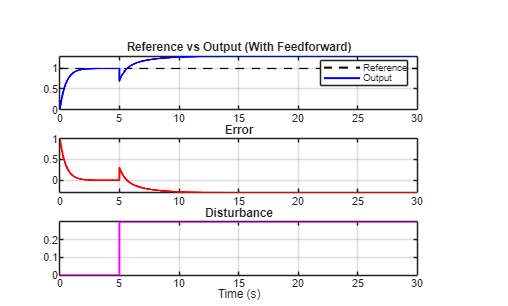

s = tf('s');

% Plant
G = 1/(s + 0.5);

% PI controller
C = 2 + 1/s;

% Feedforward gain (inverse DC gain)
Kff = 0.5;

% Time
t = 0:0.01:30;

% Reference
r = ones(size(t));

% Disturbance (known, predicted)
d = 0.3*(t >= 5);

% Closed-loop transfer functions
T = feedback(C*G,1);      % Complementary sensitivity
S = feedback(1,C*G);      % Sensitivity

% ===== Feedforward + Feedback output =====
y = lsim(T,r,t) ...
    - lsim(S,d,t) ...
    + lsim(G*Kff,d,t);

% Error
e = r - y;

% ================= PLOTS =================
figure;

subplot(3,1,1)
plot(t,r,'k--',t,y,'b','LineWidth',1.5)
grid on
title('Reference vs Output (With Feedforward)')
legend('Reference','Output')

subplot(3,1,2)
plot(t,e,'r','LineWidth',1.5)
grid on
title('Error')

subplot(3,1,3)
plot(t,d,'m','LineWidth',1.5)
grid on
title('Disturbance')
xlabel('Time (s)')


% ============ PERFORMANCE METRICS ============
idx = find(t>=5);
e_d = abs(e(idx));

max_error = max(e_d)

max_error = 0.3000


band = 0.02;
peak_idx = find(e_d==max_error,1);
rec_idx = find(e_d(peak_idx:end)<band,1);

recovery_time = t(idx(peak_idx+rec_idx-1)) - 5

recovery_time = 0.5800

The feedback-only PI controller produces a peak error equal to the disturbance magnitude and rejects it within approximately 1.36 s.

With feedforward control based on inverse DC gain, the peak error remains unchanged, but the recovery time improves significantly to about 0.58 s.

c) Performance Comparison:

fprintf("c) Performance Comparison:");

c) Performance Comparison:

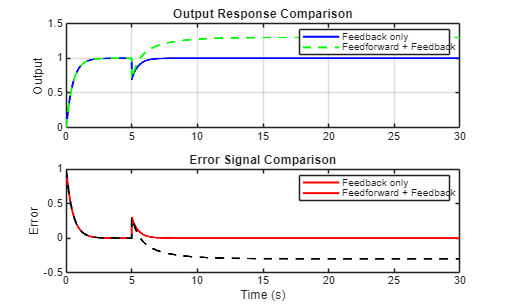

s = tf('s');

% Plant
G = 1/(s+0.5);

% PI controller
C = 2 + 1/s;

% Feedforward gain
Kff = 1/dcgain(G);   % = 0.5

% Time
t = 0:0.01:30;

% Reference
r = ones(size(t));

% Disturbance
d = 0.3*(t>=5);

% Sensitivity functions
T = feedback(C*G,1);     % Complementary sensitivity
S = feedback(1,C*G);     % Sensitivity

% ===============================
% FEEDBACK ONLY
% ===============================
y_fb = lsim(T,r,t) - lsim(S,d,t);
e_fb = r - y_fb;

% ===============================
% FEEDFORWARD + FEEDBACK
% ===============================
y_ff = lsim(T,r,t) - lsim(S,d,t) + lsim(G*Kff,d,t);
e_ff = r - y_ff;

% ===============================
% PART (c): COMPARISON PLOTS
% ===============================
figure;

subplot(2,1,1)
plot(t,y_fb,'b','LineWidth',1.5); hold on
plot(t,y_ff,'g--','LineWidth',1.5)
grid on
title('Output Response Comparison')
ylabel('Output')
legend('Feedback only','Feedforward + Feedback')

subplot(2,1,2)
plot(t,e_fb,'r','LineWidth',1.5); hold on
plot(t,e_ff,'k--','LineWidth',1.5)
% grid on
title('Error Signal Comparison')
ylabel('Error')
xlabel('Time (s)')
legend('Feedback only','Feedforward + Feedback')

In feedback-only control, the controller reacts to the disturbance only after an error is produced, resulting in a larger recovery time. By adding feedforward control based on the inverse DC gain of the plant, the disturbance effect is partially compensated before it propagates through the system. Although the peak error remains unchanged due to transient dynamics, the recovery time is significantly reduced. The PI controller ensures zero steady-state error in both cases.

(d) Unpredicted Disturbance Test:

fprintf("(d) Unpredicted Disturbance Test:");

(d) Unpredicted Disturbance Test:

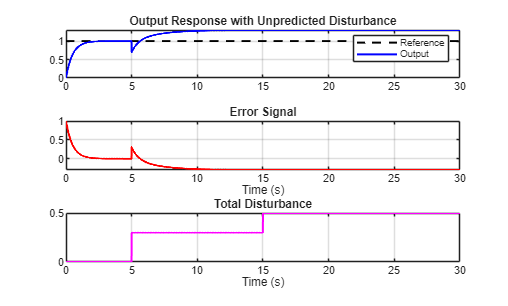

s = tf('s');

% Plant
G = 1/(s + 0.5);

% PI controller
C = 2 + 1/s;

% Feedforward gain (only for predicted disturbance)
Kff = 1/dcgain(G);   % = 0.5

% Time
t = 0:0.01:30;

% Reference
r = ones(size(t));

% Disturbances
d_pred = 0.3*(t >= 5);     % predicted disturbance
d_unpred = 0.2*(t >= 15);  % unpredicted disturbance
d_total = d_pred + d_unpred;

% Sensitivity functions
T = feedback(C*G, 1);      % Complementary sensitivity
S = feedback(1, C*G);      % Sensitivity

% Output:

% Error
e = r - y;

% ================= PLOTS =================
figure;

subplot(3,1,1)
plot(t, r, 'k--', t, y, 'b', 'LineWidth', 1.5)
grid on
title('Output Response with Unpredicted Disturbance')
legend('Reference','Output')

subplot(3,1,2)
plot(t, e, 'r', 'LineWidth', 1.5)
grid on
title('Error Signal')
xlabel('Time (s)')

subplot(3,1,3)
plot(t, d_total, 'm', 'LineWidth', 1.5)
grid on
title('Total Disturbance')
xlabel('Time (s)')

# Observation:

- At t = 5 s (predicted disturbance)→ Small deviation (feedforward + feedback)

- At t = 15 s (unpredicted disturbance)→ Error spike appears→ Feedforward does nothing→ Feedback reduces error back to zero

Q.How feedback handles the unpredicted disturbance?

Since the unpredicted disturbance is not included in the feedforward path, it directly affects the output and produces an error. The feedback controller detects this error and adjusts the control input, thereby rejecting the disturbance and restoring the output to the reference value.

# Complementary Nature of Feedforward and Feedback:

Feedforward control improves disturbance rejection for known disturbances by compensating them in advance. Feedback control ensures robustness by correcting errors caused by unpredicted disturbances. Together, they provide fast response and reliable disturbance rejection.

Question 4

## Given MIMO system

This means:


$$G_{11} \left(s\right)=\frac{2}{s+1}\;\;\;\;\;\;\;\;\;G_{12} \left(s\right)=\frac{0\ldotp 5}{s+2}\;\;\;\;\;\;\;\;\;\;\;\;G_{21} \left(s\right)=\frac{1}{s+1\ldotp 5}\;\;\;\;\;\;\;\;\;\;\;G_{22} \left(s\right)=\frac{3}{s+1}$$


fprintf("Question 4:");

Question 4:

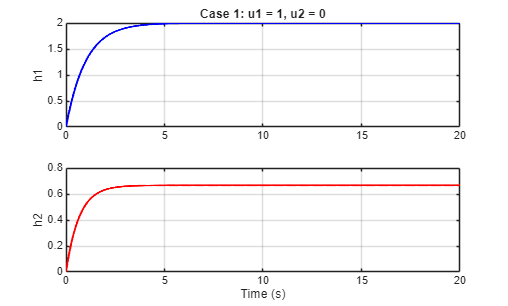

s = tf('s');

% MIMO transfer functions
G11 = 2/(s+1);
G12 = 0.5/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

% MIMO system
G = [G11 G12;
     G21 G22];

% Time (COLUMN vector)
t = (0:0.01:20)';

%% Case 1: u1 = 1, u2 = 0
u1 = ones(length(t),1);
u2 = zeros(length(t),1);
U = [u1 u2];     % Nx2

Y = lsim(G, U, t);

h1 = Y(:,1);
h2 = Y(:,2);

figure;
subplot(2,1,1)
plot(t,h1,'b','LineWidth',1.5)
grid on
title('Case 1: u1 = 1, u2 = 0')
ylabel('h1')

subplot(2,1,2)
plot(t,h2,'r','LineWidth',1.5)
grid on
ylabel('h2')
xlabel('Time (s)')

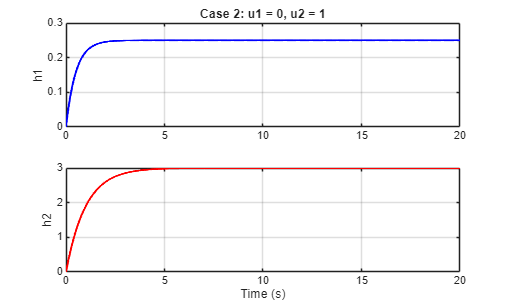


%% Case 2: u1 = 0, u2 = 1
u1 = zeros(length(t),1);
u2 = ones(length(t),1);
U = [u1 u2];

Y = lsim(G, U, t);

h1 = Y(:,1);
h2 = Y(:,2);

figure;
subplot(2,1,1)
plot(t,h1,'b','LineWidth',1.5)
grid on
title('Case 2: u1 = 0, u2 = 1')
ylabel('h1')

subplot(2,1,2)
plot(t,h2,'r','LineWidth',1.5)
grid on
ylabel('h2')
xlabel('Time (s)')

Changing one input in a MIMO system affects both outputs because each output depends on all inputs through coupling terms. One effect is direct, while the other occurs due to cross-coupling between channels.

b) Decentralized PI Control:

**Given**

- C_1: controls h1 using u1 (ignores h2)

- C_2: controls h2 using u2(ignores h1)

- Gains:Kp1=1.5,  Ki1=0.8  Kp2=1.2,Ki2=0.6

- References:r1=1.0,  r2=1.5

fprintf("b) Decentralized PI Control:");

b) Decentralized PI Control:

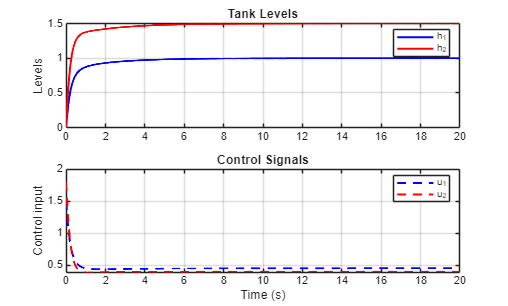

s = tf('s');

% Plant (from previous part)
G11 = 2/(s+1);
G12 = 0.5/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

G = [G11 G12;
     G21 G22];

% PI controllers (decentralized)
C1 = 1.5 + 0.8/s;   % for h1-u1
C2 = 1.2 + 0.6/s;   % for h2-u2

C = [C1  0;
     0   C2];

% Closed-loop MIMO system
T = feedback(G*C, eye(2));

% Time
t = (0:0.01:20)';

% References
r1 = 1.0*ones(length(t),1);
r2 = 1.5*ones(length(t),1);
R = [r1 r2];

% Outputs
Y = lsim(T, R, t);
h1 = Y(:,1);
h2 = Y(:,2);

% Control signals
E = R - Y;
U = lsim(C, E, t);
u1 = U(:,1);
u2 = U(:,2);

% ================= PLOTS =================
figure;

subplot(2,1,1)
plot(t,h1,'b',t,h2,'r','LineWidth',1.5)
grid on
title('Tank Levels')
ylabel('Levels')
legend('h_1','h_2')

subplot(2,1,2)
plot(t,u1,'b--',t,u2,'r--','LineWidth',1.5)
grid on
title('Control Signals')
ylabel('Control input')
xlabel('Time (s)')
legend('u_1','u_2')

c) Analyzing Interaction Effects:

1️. Observation of coupling effects:

**• Does controlling **h1** affect **h2**?**

Yes. When h1 is controlled using u1, h2  also changes due to the cross-coupling term G_21. This shows interaction between the two loops.

**• Do the outputs interfere with each other?**

Yes. Changes in one control loop cause transient deviations in the other output, indicating interference due to system coupling.

**• Is there overshoot or oscillation due to interaction?**

Small overshoots/transients may appear in both h1 and h2, but sustained oscillations are not observed. The decentralized PI controllers maintain stability.

2.Final settling values and settling times

(d) Sequential Setpoint Changes:

fprintf("(d) Sequential Setpoint Changes:");

(d) Sequential Setpoint Changes:

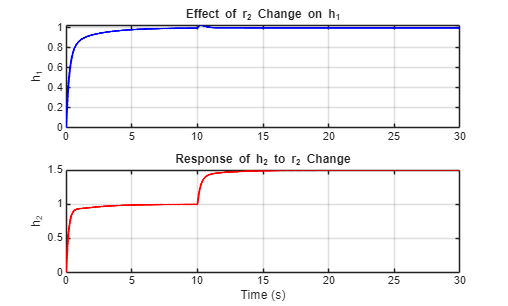

s = tf('s');

% Plant (MIMO)
G11 = 2/(s+1);
G12 = 0.5/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

G = [G11 G12;
     G21 G22];

% Decentralized PI controllers
C1 = 1.5 + 0.8/s;
C2 = 1.2 + 0.6/s;

C = [C1 0;
     0  C2];

% Closed-loop system
T = feedback(G*C, eye(2));

% Time
t = (0:0.01:30)';

% Sequential references
r1 = ones(length(t),1);                % r1 = 1 for all time
r2 = ones(length(t),1);                % r2 = 1 initially
r2(t>=10) = 1.5;                       % r2 changes at t = 10 s
R = [r1 r2];

% Outputs
Y = lsim(T, R, t);
h1 = Y(:,1);
h2 = Y(:,2);

% ================= PLOTS =================
figure;

subplot(2,1,1)
plot(t,h1,'b','LineWidth',1.5)
grid on
title('Effect of r_2 Change on h_1')
ylabel('h_1')

subplot(2,1,2)
plot(t,h2,'r','LineWidth',1.5)
grid on
title('Response of h_2 to r_2 Change')
ylabel('h_2')
xlabel('Time (s)')

# observation

- At t = 10 s, only r2 changes

- h2  responds directly

- h1 also shows a transient change, even though r1 is constant

Q. Why MIMO systems are more challenging than SISO :

In MIMO systems, each input affects multiple outputs, causing coupling and interaction. Changes in one reference can disturb other outputs, making controller design and tuning more complex than in SISO systems.

Q.How controllers could be improved:

- Use decoupling control to reduce interaction between loops

- Design multivariable (MIMO) controllers instead of independent PIs

- Apply model-based control such as state-space or MPC

# Summary questions:

1. When would you choose a lead compensator over increasing PID gains?

A lead compensator is preferred over increasing PID gains when faster response and better stability margins are needed without increasing overshoot or noise sensitivity. Increasing PID gains can make the system unstable or noisy, whereas a lead compensator adds phase lead safely.

 2. What are the main advantages and limitations of lag compensators? 

Lag compensators improve steady-state accuracy by increasing low-frequency gain and reducing steady-state error. However, they slow down the system response and increase settling time, and they do not significantly improve stability.

3. Why is feedforward control called ”proactive” compared to feedback? 

Feedforward control is called proactive because it acts in advance using known reference or disturbance information. Unlike feedback, it does not wait for an error to occur before taking action.

4. What makes MIMO systems more difficult to control than SISO systems?

MIMO systems are more difficult to control than SISO systems because each input affects multiple outputs, causing interaction and coupling. This makes controller design, tuning, and stability analysis more complex.